# The telescope package

# in the astronomy & astrophysics toolbox for MATLAB

## Description

The telescope package contains several sub packages for related to telescopes, optics, speckles simulations, signal-to-noise calculations, observatories, and telescope control.

To view all the sub packages type: "`telescope.`" followed by <tab>.

This file is accessible through "`telescope.manual`"

To avoid using the "`telescope.PTF.coo2field`" syntax, you can use:

import telescope.*
help PTF.coo2field


PTF.coo2field not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# List of sub packages

## Optics

The Optics package contains tools to simulate speckle images, and to work with Zernike functions.

The following example generates a realistic speckle image generated by the Earth atmosphere. 

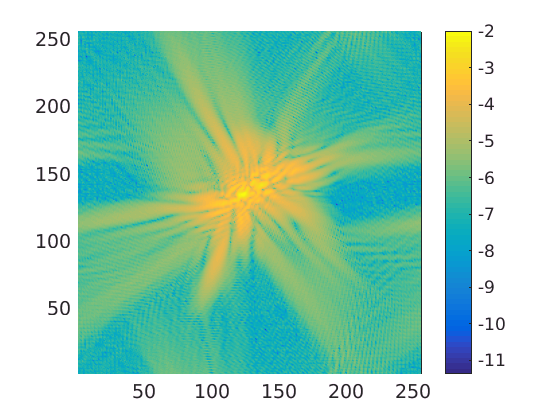


% Note that the size of the seeing disk in this example is (D/r0)*OverSamp:
% 100 terms
J = (1:1:100);
% Telescope aperture: 100 cm, Fried length: 5 cm.
D=100; r0=5;
[AmpC,J,C]=telescope.Optics.zer_cj_variance(100,'Nrand',1,'D',D,'r0',r0);
[Image_NS,Image,SumY]=telescope.Optics.zerwavefront2image(J,[],C);
pcolor(log10(Image)), shading interp; axis square, colorbar

## sn

This package contains S/N calculators and tools including functions for calculating the S/N for detection and measurments assuming PSF or aperture photometry .

High level function - S/N for photometry:

The `telescope.sn.sn_calc` is a general function for calculating a S/N of a telescope. This function take into account a large number of effects, and it can calculate either the limiting magnitude for a given S/N (for photometric measurment):

[SN,Par]=telescope.sn.sn_calc('SN',5,'ExpTime',60,'Aper',100,'FocalLength',1000,'Family','SDSS','Band','g','AM',2,'FWHM',1,'PixSize',15,'RN',5)

SN =                  Mag: 21.915
            VarRatio: [1×1 struct]
                  SN: 4.9982
         BestPhotRad: 0.6
    FracInCentralPix: 0.091125
       SaturationMag: 12.679
               SNrad: [1×500 double]
             PhotRad: [1×500 double]
              Signal: 221.78
                 Var: [1×1 struct]
              Noise2: [1×500 double]
    NpixBestPhotAper: 12


Par =           PixScale: 0.3094
         ccdFOVdim: [1856.4 1856.4]
        ccdFOVarea: 0.26591
        totFOVarea: 1.8614
           ExpTime: 60
        totExpTime: 60
       ExtinFactor: 1.3799
             Flux0: 5.7679e-06
           Counts0: 1.3334e+06
              Area: 7854
           EffArea: 3534.3
       BckCountsAS: 18.761
      BckCountsPix: 1.7959
     ScBckCountsAS: 0
    ScBckCountsPix: 0


or S/N for a given magnitude:

[SN,Par]=telescope.sn.sn_calc('Mag',21,'ExpTime',60,'Aper',100,'FocalLength',1000,'Family','SDSS','Band','g','AM',2,'FWHM',1,'PixSize',15,'RN',5)

SN =                  Mag: 21
            VarRatio: [1×1 struct]
                  SN: 10.851
         BestPhotRad: 0.8
    FracInCentralPix: 0.091125
       SaturationMag: 12.976
               SNrad: [1×500 double]
             PhotRad: [1×500 double]
              Signal: 677.43
                 Var: [1×1 struct]
              Noise2: [1×500 double]
    NpixBestPhotAper: 22


Par =           PixScale: 0.3094
         ccdFOVdim: [1856.4 1856.4]
        ccdFOVarea: 0.26591
        totFOVarea: 1.8614
           ExpTime: 60
        totExpTime: 60
       ExtinFactor: 1.3799
             Flux0: 5.7679e-06
           Counts0: 1.3334e+06
              Area: 7854
           EffArea: 3534.3
       BckCountsAS: 18.761
      BckCountsPix: 1.7959
     ScBckCountsAS: 0
    ScBckCountsPix: 0


See help `telescope.sn.sn_calc` for additional options.

High level function - S/N for spectroscopy:

The `telescope.sn.sn_spec` function can calculate the S/N for spectroscopic instruments, taking into account, telescope, atmospheric, CCD and instrumental effects. It calculate the S/N per resolution element assuming optimal extraction.

% Read an input spectrum
Spec = AstSpec.get_galspec('Gal_E');
% scale the spectrum magnitude
Spec = scale2mag(Spec,21);
% verify its syntheic mag
Spec.synphot('SDSS','r','AB')

ans =            21


% calc S/N assuming default parameters
SN=telescope.sn.sn_spec(Spec)

SN =           Wave: [726×1 double]
    SNperResEl: [726×1 double]
         ResEl: [726×1 double]


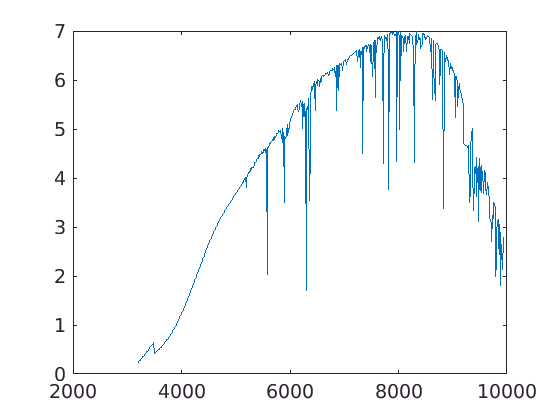

% Plot S/N per resolution element
plot(SN.Wave,SN.SNperResEl)

The user can control many subtle parameters like the throughput as a function of wavelength, the resolution as a function of wavelength and many more.

Low level functions:

The following example convert a spectrum into number of photons within a filter band. In this specific case we use a black body spectrum  with temperature of 5770 K.

[Flux,Counts]=telescope.sn.spec2photons(5770,[100 300000],[],696000e5,10)

Flux =    3.1976e-07


Counts =     1.484e+05


Furthermore several functions for calculating S/N from source flux, background and PSF are available, for PSF photometry, aperture photometry and detection.

## obs

Tools for planning observations, and general observatories.

telescope.sn.obspl is a general GUI based utility.

The following example plot a target altitude/airmass above and Moon status

/usr/local/MATLAB/R2016b/toolbox/aero/aero/geod2geoc.m


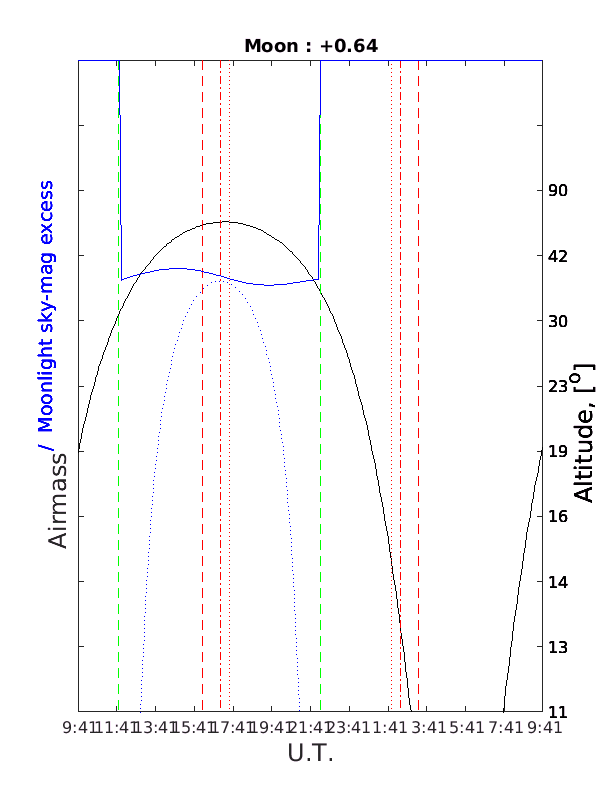

telescope.obs.daily_observability('Wise',[27 8 2001],[18 0 0],[1 67 0 0]);

and yearly observability plot

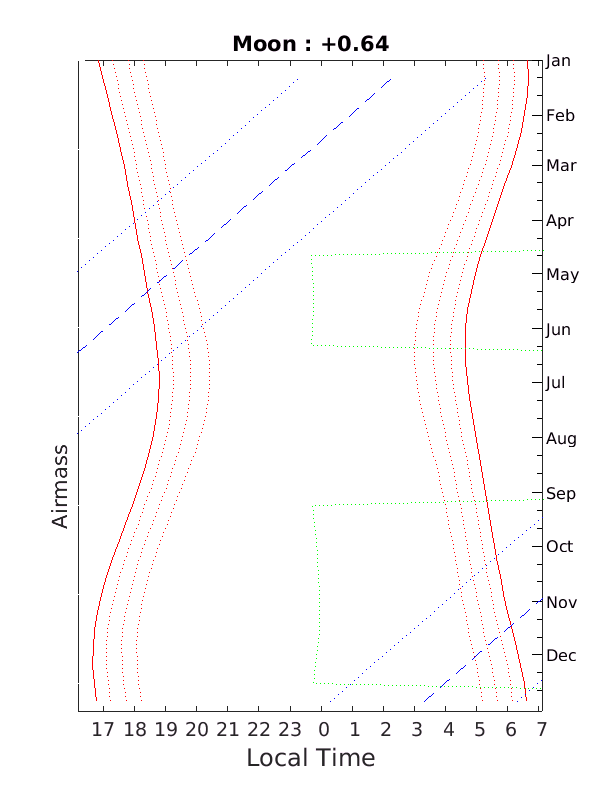

telescope.obs.yearly_observability(2001,[10 0 0 -1 20 0 0],'Wise',2,2.5);

## control

Telescope, dome and camera control.